# Coursework 1 - Completed by Yousef Abdalla (14296919)

## Predicting survival in the Titanic disaster

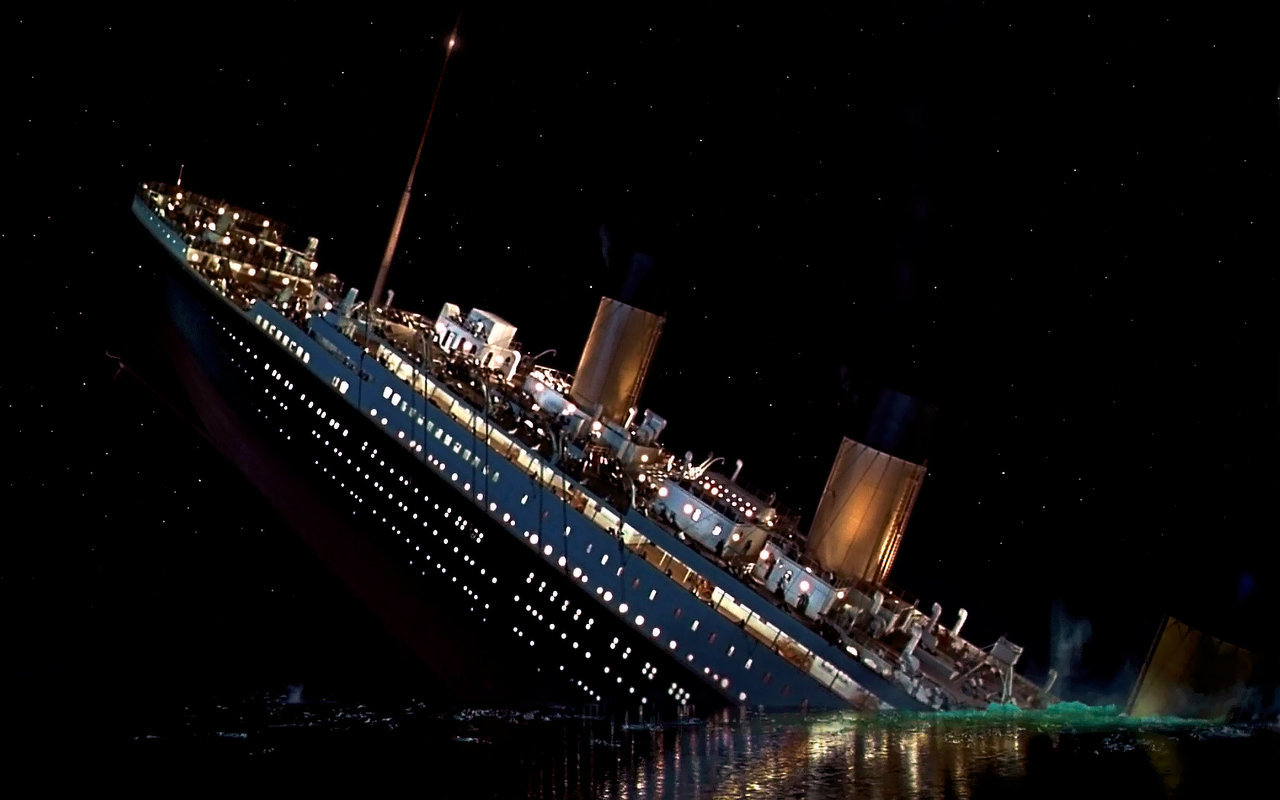

**Summary: **

On 15 April 1912, the RMS Titanic ship struck an iceberg and sank. Of the estimated 2224 passengers on board, over 1500 unfortunately did not survive. This led to significant changes in maritime safety regulations. 

With modern AI tools, it is possible to go further and ask, 'which passengers were most likely to survive'? This type of information could help in identifying the shortcomings in safety and processes.  

For this coursework student will build a classifier, based on decision trees and random forests, that will predict whether or not a passenger would survive. Students will report back on the key attributes that determine survival. 

Students will be given a partial passenger list, containing multiple data points for each passenger and whether they survived, to train your model. Part of the assessment will be to run the model on unseen passenger data and predict survival.

**Format of coursework: **

Students will be answering questions posed in this `.mlx` workbook - these will take the form of *written* **and*** coded *answers. Student answers should be amended into this `.mlx` workbook:  

- Places for students to put *written* *answers* are denoted as:

*[Write your answers here]*

For these, full and detailed answers with justifications are expected - single word answers will not achieve high marks (see rubric).  Students may also add additional code to these sections to support their answers by inserting code sections:

- Places for students to *insert code answers*, where required, are written as:

% Write your code here

Consideration should be given to writing neat, efficient code with suitable commenting to gain full marks (see rubric). If your code is slow to run consider limiting outputs using semicolons at the end of lines or using section breaks and only running the current section:

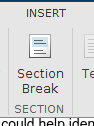

- Students will also be required to *write function files* for use within this workbook. Students should use the recommended file names, and place the file in the same directory as this workbook. 

**Marks:** 

This coursework is worth 30% of the module grade. The marking rubric is available on Moodle. The marks available for each section are shown in the workbook - sections add to 90% of total mark, with a further 10% to be awarded for good coding practice (see rubric for more details).

**Submission: **

- Students are required to submit this MATLAB live script (`.mlx`) with your answers amended to it, plus any additional functions files produced (`.m/.mlx)`.

- In addition you must also *print *this workbook to a `.pdf` file using the '*Save* > *Export to PDF*' button. 

- Put *all* your files into a single `.zip` archive - other compression formats will NOT be accepted.

- The code in the submitted `.mlx` file must be able to run *without* any modification by the assessor.

- The student must submit their assignment via Moodle ONLY.  

The coursework will be assessed based on the` .mlx` file students submit, with the `.pdf` file used as a record of what results your machine produced. Students that do not submit their `.mlx` file will not get any marks ('No code' as per the rubric). Please also carefully check the submission before uploading to Moodle - only the submitted .mlx file will be assessed.

**Software/toolboxes required: **

- MATLAB 

- Bioinformatics Toolbox

- Statistics and Machine Learning Toolbox

- Curve Fitting Toolbox.

**Deadline: **

Thursday 25 March 2021, 15:00 (UK time) - submission via Moodle Page *only* (https://moodle.nottingham.ac.uk/mod/assign/view.php?id=4842253)

**Files: **

The file `passengers.csv` contains a list of some of the passengers and their details (attributes). The file `passengersVal.csv` contains a subset of passengers that students will use for validating their model in Part 4. The attributes of the dataset provided are described in the file `attributes.pdf`

**IMPORTANT NOTE: **

The assessors will be using MOSS ([http://theory.stanford.edu/~aiken/moss/](http://theory.stanford.edu/~aiken/moss/)) to check for similarity between pieces of code - students submission will be checked against other students' code from this year, previous years student's code, and code available online. In addition, your written answers will also be checked using TurnItIn.

This coursework is an individual assignment – it is expected that students DO NOT collaborate on the coursework assignment as they should be WRITING THEIR OWN CODE. Sharing or plagiarising other’s work constitutes a serious academic offence. Last year, 11 cases of significant copying were detected, leading to the students failing the module.  

## Part 1: Data analysis and plotting (20%)

To start with, make sure you can load the data and can plot it.  For example:

clc;
close all;
clear variables;

passengerData = readtable('passengers.csv');

We can then plot a pie chart of the sex of those who died:

passengerSex = passengerData.sex;
passengerSurvival = passengerData.survived;

% Produce a logical type ('true' or 'false') list indicating those who survived
survivors = (passengerSurvival == 1);

sexOfNonSurvivors = passengerSex(~survivors); %Sex of those who did not survive
maleNonSurvivors = strcmp(sexOfNonSurvivors,'male');
nMaleNonSurvivors = sum(maleNonSurvivors); %Number of male non-survivors
nFemaleNonSurvivors = sum(~maleNonSurvivors);
pie([nMaleNonSurvivors,nFemaleNonSurvivors],{'male','female'});
title('Sex of non-survivors');
legend('Male Casualties', 'Female Casualties', 'Location',"southoutside");

### Tasks:

***1.*** Plot two pie charts: the first should show the gender split of survivors and the second should show the gender split of all passengers.

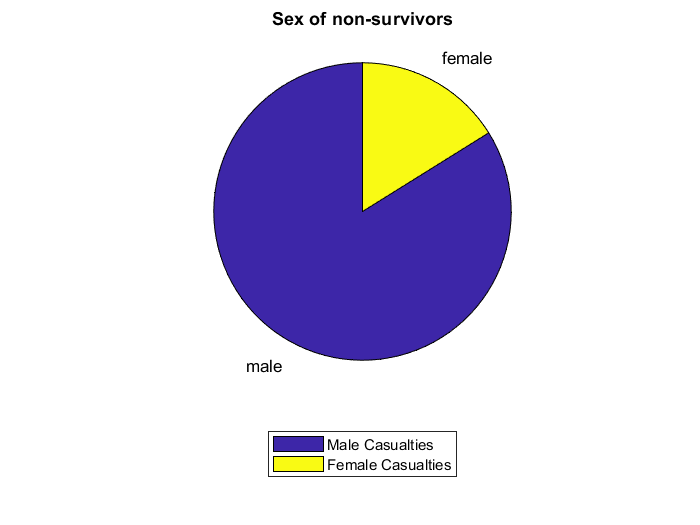

% Write your code here

% Pie chart showing the gender split of survivors
sexOfSurvivors = passengerSex(survivors);                   % Extract genders of Survivors
maleSurvivors = strcmp(sexOfSurvivors, 'male');             % Extract Male Survivors
nMaleSurvivors = sum(maleSurvivors);                        % Count Male Survivors

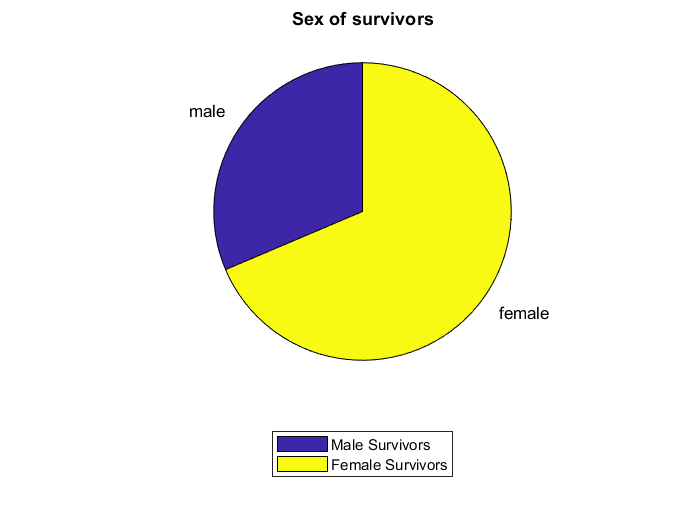

nFemaleSurvivors = sum(~maleSurvivors);                     % Count Female Survivors
pie([nMaleSurvivors,nFemaleSurvivors],{'male','female'});   % Plot Pie chart

% Add Title and legend
title('Sex of survivors');
legend('Male Survivors', 'Female Survivors', 'Location',"southoutside");

% Pie chart showing the gender split of all passengers
malePassengers = strcmp(passengerSex,'male');               % Extract Male Passengers
nMalePassengers = sum(malePassengers);                      % Count Male Passengers
femalePassengers = strcmp(passengerSex, 'female');          % Extract Female Passengers
nFemalePassengers = sum(~malePassengers);                   % Count Female Passengers
pie([nMalePassengers,nFemalePassengers],{'male','female'}); % Plot Pie chart

% Add Title and legend

title('Sex of passengers');
legend('Male Passengers', 'Female Passengers', 'Location',"southoutside");

What difference do you notice in the gender balance?

*    - Initially, there were more male passengers on the ship than there were female passengers, 63.7% and 36.3% respectively. This difference in ratio sheds some light on why the pie chart labelled "Sex of non-survivors" looks the way it does. From this pie chart one can work out that from all the casualities, 83.9% were male passengers and 16.1% were female passengers, and although this difference is higher than the initial gender gap, it still follows the same trend and is therefore undoubtly related. *

*Moving on to the final pie chart labelled "Sex of survivors", as one would expect given the previously mentioned facts, there were more female survivors than there were male survivors, however, from this data alone, one can not conclude why the majority of the male passengers died in this tragic incident, whilst the majority of the female passengers survived.*

***2.*** Plot two histograms: the first should show of the ages of survivors and the second should show the ages of non-survivors. These should be plotted on top of one another and each should be identified using a legend. You may find the following command useful:

For information on how to use this function type:

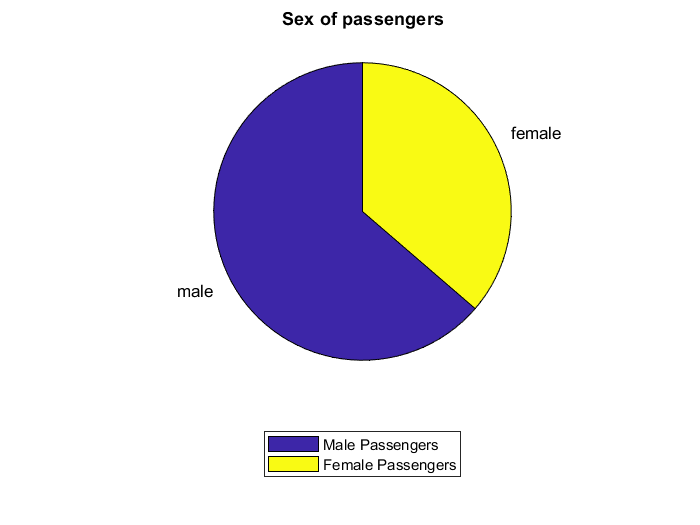

% Write your code here
passengerAge = passengerData.age;                   % Extract passengers' ages

% Histogram showing the ages of survivors
ageOfSurvivors = passengerAge(survivors);           % Extract age of survivors
histogram(ageOfSurvivors);                          % Plot histogram
hold on;                                            % Prepare to superpose next plot

% Histogram showing the ages of non-survivors

ageOfNonSurvivors = passengerAge(~survivors);       % Extract age of non-survivors
histogram(ageOfNonSurvivors);                       % Plot and superpose second histogram
legend('Age of Survivors','Age of Non-Survivors');  % Add legend
xlabel('Age');                                      % Add X-label
ylabel('Number of passengers');                     % Add Y-label
title('Survival based on age');                     % Add title to plot
hold off;

Comment on the difference in age distributions of survivors vs. non survivors observed from the histograms.

*    - Initially, the majority of the passengers on board were between the ages of 15-40, which as expected resulted in most casualities and survivors being from this age group. Of note is the fact that these histograms account for only 80% of the passengers on board as 228 (*≈ 20%) *of the passengers' ages are unknown, i.e. missing from the data set. As a result, this limits the accuracy of the plot because it does not provide a complete picture, but rather 4/5 of it.*

*Furthermore, the only age groups in which there were more survivors than casualities are ages 0-10 and 75-80, which may be a result of the young and elderly being saved first; and the only age group which had no survivors was 65-75.*

***3. ***Many passenger entries in the dataset do not contain entries in all fields: for example 'age' is often missing. Calculate the proportion of passengers in each of first, second and third class whose age data is not known and plot this data in bar chart.  The x-axis should be 'class of travel' and the y-axis should be 'proportion of passengers with missing age data'. Note that blank entries in the raw `.csv` file (if opened in MS Excel for example) correspond to `NaN` entries in MATLAB. 

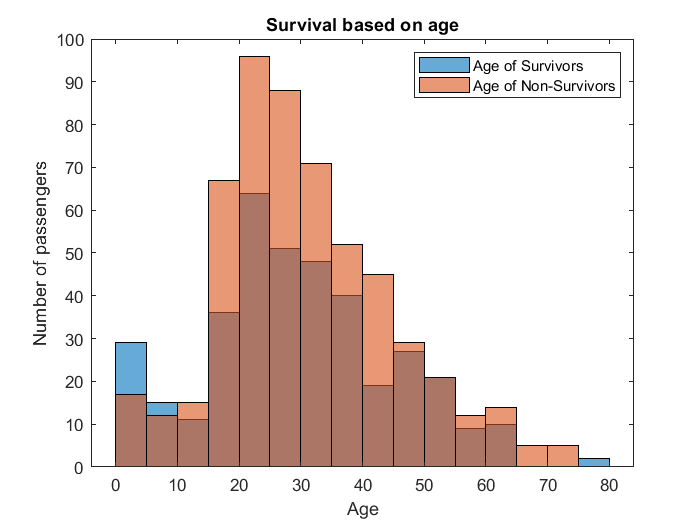

% Write your code here

% Extract the passengers' class and age from main data
passengerClassAge = passengerData(:,[1,5]);

classes = categorical(passengerClassAge.pclass);  % Categorize the classes
classes = categories(classes);                    % Extract distinct categories

% Extract the passengers details from ClassAge table for each class
class1PassengerAges = passengerClassAge(passengerClassAge.pclass == 1, :);
class2PassengerAges = passengerClassAge(passengerClassAge.pclass == 2, :);
class3PassengerAges = passengerClassAge(passengerClassAge.pclass == 3, :);

% Produce a logic table 1 or 0 to indicate of data is not available
class1nans = isnan(class1PassengerAges.age);
class2nans = isnan(class2PassengerAges.age);
class3nans = isnan(class3PassengerAges.age);


% Work out the proportion of ages missing in each class by summing the logic table
class1nansPortion = nnz(class1nans)/size(class1nans,1);
class2nansPortion = nnz(class2nans)/size(class2nans,1);
class3nansPortion = nnz(class3nans)/size(class3nans,1);

% Convert proportions to vector
classProp = [class1nansPortion; class2nansPortion; class3nansPortion];

% Convert to suitable format and plot as a bar chart
bar(str2num(cell2mat(classes)),classProp);

% Add labels to plot
hold on;
xlabel('Class of Travel');
ylabel('Proportion of passengers');
title('Proportion of passengers with missing age data in each class')
hold off;

***4. ***The variable `cabin` in the table contains the cabin numbers for some of the passengers on the ship.  Write code that can* a)* determine the number of unique cabin numbers listed, *b)* identify the cabin(s) associated with the largest number of passengers (i.e. cabin with most people) and *c)* find the number of people in that cabin(s).  Your code should print the answers to the command line. *Hint: *you may like to read more about categorical arrays in MATLAB: [https://uk.mathworks.com/help/matlab/categorical-arrays.html](https://uk.mathworks.com/help/matlab/categorical-arrays.html))

% Write your code here

% Part a
cabinIdsI = categorical(passengerData.cabin); % Extract cabins column from main data
cabinIds = categories(cabinIdsI);             % Identify unique categories
ncabinIds = size(cabinIds,1);                 % Count number of unique categories

% Part c
% Identify the number of people each cabin is associated with
cabinOccurences = countcats(cabinIdsI);
% Identify the maximum number of people in a cabin
mostPeopleInCabin = max(cabinOccurences);

% Code that identifies the busiest cabins (part b)
busiestCabins = cabinIds(cabinOccurences == mostPeopleInCabin);

% Outputs
Part_a = ncabinIds           % Unique Cabin IDs
Part_b = busiestCabins       % Cabins with most people
Part_c = mostPeopleInCabin   % Most People in cabin

## Part 2: Dealing with missing data (20%)

Given the large proportion of missing data, we must find a strategy to train a classifier without introducing *bias - *for example, it might be that older people were less likely to divulge their age to the ticketing office. To do this, we could simply exclude all data points that are missing values but this has a critical problem - we might need to classify a new data point that has missing data.  We therefore need a more robust strategy. This part will explore three strategies for dealing with missing data.

### Tasks

***1.*** *Method 1: *Generate a copy of the `passengerData` dataset, called `passengerData_av`.  For this new data set, write code that for each of the attributes `{'age', 'fare', 'embarked'}` finds any missing values and replaces them with an average value. You will need to figure out how to deal with different data types (numerical or categorical) and consider different averaging methods for different types, e.g. mean median, mode.

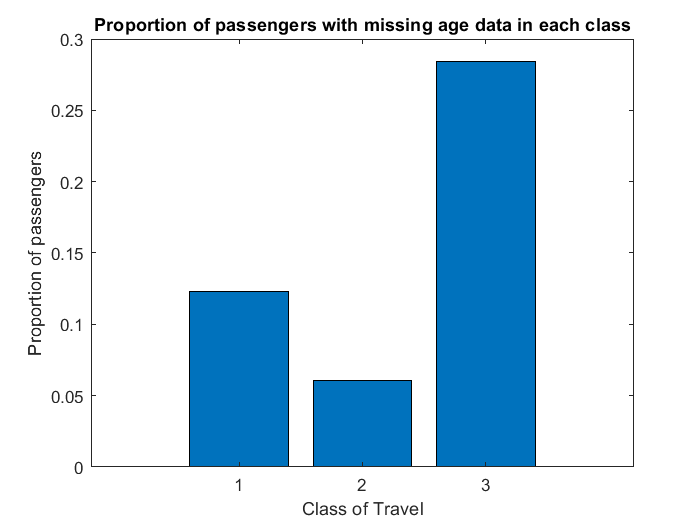

% Write your code here
passengerData_av = passengerData;         % Generate a copy of the passengerData dataset

nPassengers = size(passengerData_av,1);   % Identify number of passengers

% Work out the average age
averageAge = mean(passengerData_av.age(~isnan(passengerData_av.age)));
% Replace age Nans with average age
passengerData_av.age = fillmissing(passengerData_av.age,"constant",averageAge);

% Work out median Fare
averageFare = median(passengerData_av.fare(~isnan(passengerData_av.fare)));
% Replace Nans with median fare
passengerData_av.fare = fillmissing(passengerData_av.fare,"constant",averageFare);

% Work out mode of embarked (most common value)
averageEmbarked = mode(cell2mat(passengerData_av.embarked));
% Replace Nans with mode embarked
passengerData_av.embarked = fillmissing(passengerData_av.embarked, ...
    "constant", averageEmbarked);


***2.*** *Method 2:* This method finds the 'most similar' data point and copies over the missing value from that. This is called the 'nearest neighbour' approach. We need to consider how to compute the similarity (or distance) between data points that contain a mixture of numerical and categorical values. Here, we will use MATLAB's built-in function:

*Note: *you need to have installed the Bioinformatics Toolbox to use this function.  

Generate a copy of the `passengerData` dataset, called `passengerData_nn`, that uses `knnimpute` to fill in missing values for the attributes `{'age', 'fare', 'embarked'}`.  *Hint*: You will first need to select only the relevant columns from the original data set.  You will also need to convert some columns to a categorical datatype.  You will ned to think about how to convert categorical variables to numbers.

% Write your code here


Part_a =    178


passengerData_nn = passengerData;   % Generate a copy of the original dataset

Part_b = 2×1 cell array
    {'C23 C25 C27'}
    {'G6'         }


Part_c =      5


dataToImpute = passengerData_nn(:,["age","fare"]);  % Extract Age and Fare Columns

% Extract Embarked Column
% -> Convert to Categorical -> Convert to Numerical
EmbarkedCategorical = categorical(passengerData_nn.embarked);
EmbarkedNumerical = grp2idx(EmbarkedCategorical);

% Add the Numerical Embarked Column and a Column of ones to dataToImpute
% then -> Convert table to array
dataToImpute = table2array(addvars(dataToImpute, EmbarkedNumerical , ones(1159,1)));

dataToImpute = dataToImpute';           % Transpose
ImputedData = knnimpute(dataToImpute);  % Impute using nearest neighbour
ImputedData = ImputedData';             % Transpose again to return to original form

% Insert imputed values into relevant columns in table
passengerData_nn.age = ImputedData(:,1);
passengerData_nn.fare = ImputedData(:,2);
passengerData_nn.embarked = discretize(ImputedData(:,3),3,'categorical' ,{'C' 'Q' 'S'});


***3.*** In task 2 you may have noticed that there is one value missing from the `'fare'` attribute.  Compare your estimated values for the missing fare using the average approach and the nearest neighbour approach. Which do you think is more realistic given the other information about the passenger?

% Write your code here

missingFareID = find(isnan(passengerData.fare));    % Obtain ID of missing fare

% Plot a scatter graph of the fare of all customers
gscatter(1:nPassengers,passengerData.fare);

% Add labels and limits
xlabel('Passenger ID');
ylabel('Fare');
title('Passenger Fares');

% View average and nearest neighbour value side by side
Comparator = [passengerData_av.fare(missingFareID) passengerData_nn.fare(missingFareID)]

*    - By looking at the scatter plot, at the first glance, one can observe that most fares were lower than 100 (≈94% of all passengers), and by zooming further into the plot (setting the Y-axis limit to 100), one can more clearly see the distribution of fares and make a second observation, which is the fact that most of the fares are actually under 30. The following line of code allows us to see the percentage of fares that were under 30, which accounts for ≈73% of all passengers. *

FareUnder30 = size(passengerData(passengerData.fare < 30, :),1)/nPassengers
% ylim([0 100]);    Uncomment to see 94% of passengers' fares
% ylim([0 30]);     Uncomment to see 73% of passengers' fares

*    - From this, one can conclude that between the average value of 14.5 and the nearest neighbour value of 33.6, the average value is the more probable and realistic estimation (According to the distribution of the remaining passenger fares). This can be linked to the fact that most passengers were travelling in the third class, for which ticket fares are cheaper.*

***4.*** *Method 3: *In this case you will create new attributes that determine whether or not the data is missing. For example, you will create a new variable called  `'is_age_missing'`.  Generate a copy of the `passengerData` dataset, `passengerData_newAttr`, that contains new attributes indicating a missing value for the attributes `{'age', 'boat', 'body'}.  `These will be called `is_age_missing``, ``is_boat_missing`, and `is_body_missing `respectively.

% Write your code here

% Generate a copy of the passengerData dataset
passengerData_newAttr = passengerData;

% Identify the missing rows in each of the following columns and produce logical array
is_age_missing = isnan(passengerData_newAttr.age);      % Age
is_boat_missing = isnan(passengerData_newAttr.boat);    % Boat
is_body_missing = isnan(passengerData_newAttr.body);    % Body

% Add these columns to the new table
passengerData_newAttr = addvars(passengerData_newAttr, is_age_missing, ...
    is_boat_missing, is_body_missing);


## Part 3: Computing entropy (25%)

### Tasks:

***1. ***Write a function that takes as input an array containing data class (i.e. whether a passenger survived or not), and a list of all possible data classes ('survived' or 'not survived' here - represented by `1` or `0`), and computes the entropy.  It should have the following form:

This should be in a new file called `calcEnt.m` (or `calcEnt.mlx` if you prefer).  To check that it works, run the following:

testIn = categorical([1,1,1,1,0,0,0,0,1,0,0,0,0]);
classList = categories(testIn);
testCalcEnt = calcEnt(testIn,classList)

The result should be:

Students may find the notes from Lectures 1 and 2 helpful.

***2. ***Write another function that takes as input a continuous valued column of data, the associated data classes, and a threshold value and returns the information gain for splitting at that threshold.  Your function should have the following form:

This should be in a new file called `calcEntThresh.m` (or `calcEntThresh.mlx` if you prefer). Your code should call the `calcEnt` function you wrote in task 1 to calcuate the total entropy and the specific conditional entropy above and below the split. To confirm your code is correct, run the following:

ageData_test = [10,11,12,17,25,46,48,49,50];
testIn_test = [0,0,0,1,1,1,0,0,0];
threshVal_test = 20;
testEnt = calcEntThresh(ageData_test,testIn_test,threshVal_test)

The result should be:

Next, run the following code on the age variable from your `passengerData_av` data to compute the information gain for a threshold of 5:

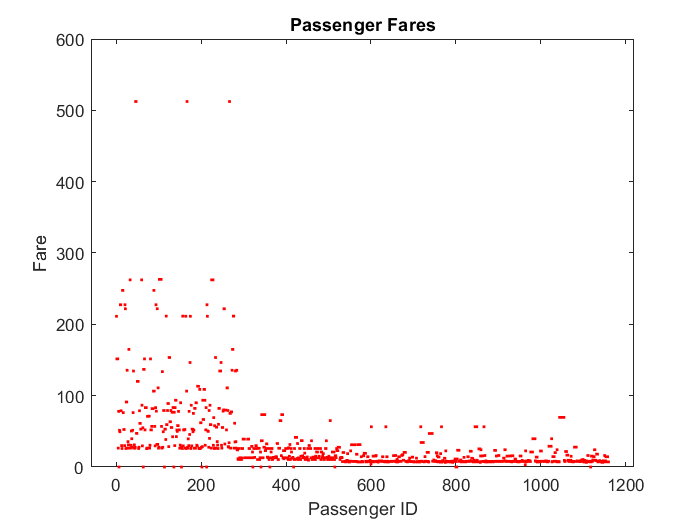

ageData = passengerData_av.age;
testIn = passengerData_av.survived;
threshVal = 5;

testEnt = calcEntThresh(ageData,testIn,threshVal)

The result should be:

***3. a)*** Using your `calcEntThreshFunction`, apply the threshold finding algorithm you learnt in Lecture 2 (when we applied it to iris data) to find the information gain at each of these thresholds.  Specifically sort passengers by age and find adjacent values where the class (i.e. survived or not) changes and test a threshold halfway between these two age values.  Plot a graph showing the information gain for every threshold tested.

% Write your code here


Comparator =   14.456250000000001  33.608458635578565


% Sort the columns age and survived
[age_sorted, sortIdex] = sort(passengerData_av.age,1,"ascend");

FareUnder30 =    0.731665228645384


survived_sorted = passengerData_av.survived(sortIdex);

% Find the number of categories in survived
classes = categories(categorical(survived_sorted));
nClasses = numel(classes);

% Compute number of elements in data set
n_data = size(passengerData_av,1);

% Compute the total entropy for the data set
ent_val_tot = calcEnt(survived_sorted,age_sorted);

% Loop through from second to last element
for n=2:n_data
    
    % Check if survived field changes ------------% 1st suggested way of speeding up
    if survived_sorted(n) ~= survived_sorted(n-1) % && age_sorted(n) ~= age_sorted(n-1)
        
        % Threshold candidate found
        thresholdCandidate = (age_sorted(n,:) + age_sorted(n-1,:))/2;
        
        % Compute info gain of the given threshold
        infoGain = calcEntThresh(age_sorted, survived_sorted,thresholdCandidate);
        
        % Produce a plot of Threshold against Information gain
        plot(thresholdCandidate, infoGain, 'bx');
        hold on;
        xlabel('Threshold');
        ylabel('Information Gain (bits)');

testCalcEnt =    0.961236604722876


        title('Information Gain of Given Threshold');
        
    end
end
hold off;

To the nearest year, what is the optimal threshold to split the `age` variable? Justify your answer.

*    - Firstly, one should confirm that the plot is correct by comparing the information gain value obtained for the same data set used in the previous task. The threshold for that was 5 and if the plot produced were to be zoomed in, it can be observed that at the threshold value of 4, the information gain is 0.00485; and at the threshold value of 6, the information gain was 0.010063. Using these values, the average (information gain of threshold value 5) can be shown using the following line of code.*

(0.00485+0.010063)/2

*As shown, the value obtained is very close to the previously calculated value of 0.0073 indicating a high degree of correctness of the plot.*

*Having confirmed the validity of the plot, one can now use it to see that the threshold value which yields the highest information gain (optimal threshold) is 9, yielding an information gain value of approximately 0.0106. - Comparitivily higher than that of the threshold value 5 tested previously.*

***b) ***In this instance, the approach from Lecture 2 may test more threshold values than are necessary leading to long computational times.  Can you suggest a faster approach, based on your knowledge of the `age` variable?

*    - There are several ways of achieving a speed up, however, some of them come with a trade off in accuracy. For instance, commented in the code above is a suggested speedy approach, which skips the element if the age is repeated, removing potential redundancies. However, this approach has a huge implication on accuracy and in turn overall preformance. An alternative approach is to perform the same operation after computing the threshold i.e. compare the threshold with the previous value and skip next loop if they're equal. However, again, this approach would impact the accuracy. A more optimal solution would be to use one of the following:*

- *Matlab's built in optimisation functions (or function arguments)*

- *Matlab's Optimisation toolbox. *

- *Gini Impurity instead of Information gain entropy - Whose equation does not use logarithms and therefore tends to be less computationally intensive.*

***4. ***Write another function that takes as input a categorical valued column of data, the associated data classes, and an array of target categories. It should return the information gain for splitting the data into items that are in one of the target categories and items that are not. Your function should have the following form:

The testIn variable will again be whether or not each data point 'survived'. The function should be in a new file called `calcEntCat.m` (or `calcEntCat.mlx` if you prefer). Your code should call the `calcEnt` function you wrote previously to calcuate the total entropy and the specific conditional entropy for each case.  Your code should also be able to check input data points against multiple categories, e.g. in the example below check wheter the data category is in the set `{'dog','cat'} `or not.

To test your function run the following code:

dataCat_test = {'dog','dog','cat','cat','cat','fish','fish','fish','fish'};
dataCat_test = categorical(dataCat_test);
testIn_test = [1,0,1,0,1,0,1,0,1];

testEnt =    0.018310781820059


testIn_check = {'fish'};
testEnt = calcEntCat(dataCat_test,testIn_test,testIn_check)

The result should be:

Next, run your code on the `pclass` variable to compute the information gain for being in first class:

pclassData = passengerData_av.pclass;
testIn = passengerData_av.survived;
pclassCheck = [1];
testEnt = calcEntCat(pclassData,testIn,pclassCheck)

testEnt =    0.007338857562057


The result should be 

***5.*** Using your modified data table, `passengerData_newAttr`, for the attributes `{'sex', 'fare', 'ageMissing', 'boatMissing', 'bodyMissing', 'pclass'} `calculate which offers the highest information gain for the first split of a decision tree.  To test each variable you should find the maximum information gain across all target categories (for categorical variables) or across all threshold values for continuous variables.  You should use the functions you wrote for the previous tasks. You must print out the maximum information gain values for each variable to the command line.

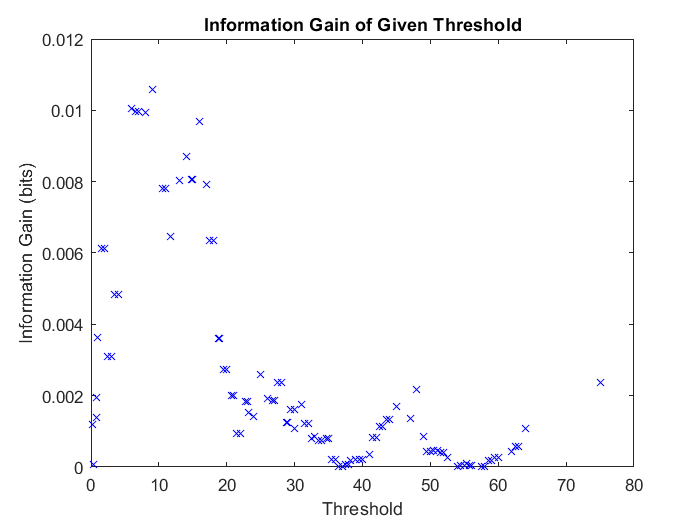

% Write your code here

% Computing Information Gain using gender
maleCheck = {'male'};
femaleCheck = {'female'};
InfoGainUsingMale = calcEntCat(categorical(passengerData_newAttr.sex), ...
    passengerData_newAttr.survived,maleCheck);
InfoGainUsingFemale = calcEntCat(categorical(passengerData_newAttr.sex), ...
    passengerData_newAttr.survived,femaleCheck);

% Computing Information Gain using Class
FirstClassCheck = [1];
SecondClassCheck = [2];
ThirdClassCheck = [3];

InfoGainUsingFirstClass = calcEntCat(passengerData_newAttr.pclass, ...
    passengerData_newAttr.survived,FirstClassCheck);
InfoGainUsingSecondClass = calcEntCat(passengerData_newAttr.pclass, ...
    passengerData_newAttr.survived,SecondClassCheck);
InfoGainUsingThirdClass = calcEntCat(passengerData_newAttr.pclass, ...
    passengerData_newAttr.survived,ThirdClassCheck);

% Computing Information Gain using missing age
InfoGainUsingAge = calcEntCat(passengerData_newAttr.is_age_missing, ...
    passengerData_newAttr.survived,[0]);
InfoGainUsingMissingAge = calcEntCat(passengerData_newAttr.is_age_missing, ...
    passengerData_newAttr.survived,[1]);

% Computing Information Gain using missing boat
InfoGainUsingBoat = calcEntCat(passengerData_newAttr.is_boat_missing, ...
    passengerData_newAttr.survived,[0]);
InfoGainUsingMissingBoat = calcEntCat(passengerData_newAttr.is_boat_missing, ...
    passengerData_newAttr.survived,[1]);

% Computing Information Gain using missing body
InfoGainUsingBody = calcEntCat(passengerData_newAttr.is_body_missing, ...
    passengerData_newAttr.survived,[0]);
InfoGainUsingMissingBody = calcEntCat(passengerData_newAttr.is_body_missing, ...

    passengerData_newAttr.survived,[1]);

% Sort fares and initalise max info gain value

ans =    0.007456500000000


fare_sorted = passengerData_av.fare(sortIdex);
MaxIUsingFare = 0;

for n=2:n_data
    % Check if survived field changes
    if survived_sorted(n) ~= survived_sorted(n-1)
        
        % Threshold candidate found
        thresholdCandidate = (fare_sorted(n,:) + fare_sorted(n-1,:))/2;
        
        % Compute info gain of a given threshold
        InfoGainUsingFare = calcEntThresh(passengerData_newAttr.fare, ...
            passengerData_newAttr.survived,thresholdCandidate);
        
        % Check if this info gain value is higher than the max recorded
        if InfoGainUsingFare > MaxIUsingFare

testEnt =    0.007214618474517


            MaxIUsingFare = InfoGainUsingFare;
        end
    end
end

% Display value of max info gains using the different attributes selected
MaxIUsingGender = InfoGainUsingMale

testEnt =    0.056779197406465


MaxIUsingClass = InfoGainUsingThirdClass
MaxIUsingMissingAge = InfoGainUsingAge
MaxIUsingMissingBoat = InfoGainUsingBoat
MaxIUsingMissingBody = InfoGainUsingBody
MaxIUsingFare    

Which attribute provides the highest information gain?   Justify your answer.

*    - The attribute that provides the highest information gain is that that, if asked, allows us to remove the largest number of records from consideration i.e. it splits the data in a way so that after asking the first question (first split in the decision tree), one can discard a significant portion of the data before asking the next question. Perhaps a good way to elaborating on this is by using some numbers, we saw previously that the gender split on at the start of the Titanic trip was 63.7% to 36.3% (Males:Females), this means that if the first question asked was "What is the gender of the passenger?", the following tree branches will either have 63.7% of the original dataset, or 36.3% of the original dataset. This provides a decent information gain, however it is only the second best attribute. Shown below is a code snippet that produces a visual representation of the information gain obtained by using each of the specified attributes. Note that the plot only includes the highest information gain that can be obtained from each attribute, rather than the InfoGain of each category or threshold.*

% Create variables of both axes
X = categorical({'Gender','Fare','Age Missing','Boat Missing', 'Body Missing', 'Class'});
X = reordercats(X,{'Boat Missing', 'Gender', 'Body Missing', 'Fare', 'Class', 'Age Missing'});
Y = [MaxIUsingGender MaxIUsingFare MaxIUsingMissingAge MaxIUsingMissingBoat MaxIUsingMissingBody MaxIUsingClass];

% Plot a bar chart, add labels and a title
bar(X,Y);
xlabel('Attributes');
ylabel('Information Gain (bits)');
title('Comparison of Information Gain using different Attributes');

hold off;

*    - From this plot one can see, that using the is_boat_missing attribute is the one that produces the highest information gain i.e. if the first question asked was "Was the boat missing?", the data would be split in a better way than the split of gender, because in the case that the answer is "no", approximately 70% (68.94% exactly) of the data can be discarded leaving the remaining 30% of the data for the remainder of the decision tree, and in case the answer was "yes", an assumption can be made and all passengers associated with that boat can be marked survived = 0.*

What would you recommend to use for the first decision? Justify your answer.

*    - In order to produce a decision tree that is as short as possible, the maximum possible amount of records must be discarded with every decision, and seeing that the is_boat_missing attribute is the attribute that would allows this, it makes sense for the first question of the tree to be "Was the boat missing?". From a probability prospective, answering this question will either discard 799 records, or will discard 360. (Comparatively better than 421:738 split of gender, and 111:1048 split of is_body_missing)*

Could `is_boat_missing` or `is_body_missing` realistically be used for prediction in future situations? Justify your answer.

*    - No, however, using AI techniques one can analyse a dataset of under 1200 elements like the one given and train an intelligent system to predict missing information about the remainder of the complete dataset of 2200 passengers, while also being able to compute the degree of correctness (accuracy) of the predictions, i.e. information like whether the boat or the body was missing can be used to know whether certain passengers survived by association, however, it can not realistically be used to predict such information for future situations where most aspects (of the dataset) would be completely different.*

### Part 4: From Decision Trees to Random Forests (25%)

In real applications, we don't typically code our own entropy computation functions from scratch - we instead exploit the multitude of pre-existing libraries.  Here, you will train decision trees and random forests using MATLAB's Statistics and Machine Learning Toolbox.

### Tasks

***1. a)*** Take your `passengerData_newAttr` dataset generated in Part 2 and remove all attributes except `{'pclass', 'sex', 'age', 'sibsp', 'parch', 'fare', 'embarked', 'ageMissing'}` to create a new dataset *.  *You may find it useful to consult the MATLAB documentation on using tables ([https://uk.mathworks.com/help/matlab/tables.html?category=tables](https://uk.mathworks.com/help/matlab/tables.html?category=tables))

% Write your code here

% Create a subset of the passengerData_newAttr dataset
passengerData_newAttr_partial = removevars(passengerData_newAttr, ...
    {'survived','name','ticket','cabin','boat','body', ...
    'home_dest','is_boat_missing','is_body_missing'});

% Extract the survived column from the passengerData_newAttr dataset
survivedData = passengerData_newAttr(:,2);


***b)*** Next, split `passengerData_newAttr_partial` and the corresponding data classes into a training and validation set (`passengerData_newAttr_train, ` `passengerData_newAttr_val, testIn_train, testIn_val `respectively). It is up to you to decide what a sensible training/validation split ratio would be.

% Write your code here
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% potential increase of accuracy for ignoring nans

% Split the data IDs into a training and a validation set (85:15)
train_prop = cvpartition(n_data,'HoldOut',0.15);
testIn_train = training(train_prop);
testIn_val = test(train_prop);

% Insert training and validation data using IDs into the relevant variables
passengerData_newAttr_train = passengerData_newAttr_partial(testIn_train,:);
survivedData_train = survivedData(testIn_train,:);
passengerData_newAttr_val = passengerData_newAttr_partial(testIn_val,:);
survivedData_val = survivedData(testIn_val,:);


***c) ***Now fit a decision tree using the `fitctree` function and plot it using the `view` function with the name-value argument `'Mode', 'graph'`.  By default, the decision tree does not use the entropy metric you learned about in Lectures 1 and 2. To use entropy, you must configure your decision tree to use the `deviance` metric (another term for entropy). You should also tell the fitting algorithm which variables are 'categorical', otherwise it assumes all are continuous valued - this can be done using the `'CategoricalPredictors'` argument (see documentation on `fitctree` for further details).

% Write your code here

% Fit and view tree
t = fitctree(passengerData_newAttr_train, survivedData_train, ...
    "SplitCriterion","deviance", ...
    "CategoricalPredictors", ["is_age_missing",'sex', "pclass", "embarked","sibsp","parch"]);
view(t,'Mode','graph');

Looking at the tree, what are the first, second and third most important attributes for determining survival? Justify your answer.

*    - As observed from the tree, the most important attributes are the **gender,** followed by the **class**, and thirdly the **fare**. *

*    - In most of the branches of the decision tree, these attributes form the first three questions asked, this gives us an indication that these three questions collectively have the highest information gain. This makes sense as it matches, to a great extent, with the previously computed information gains.*

Predictor importance can also be esimated using the `predictorImportance` function.  Use this function to determine the top 3 most important predictors.  Does this agree with your previous answer?   Compare this with your manually computed entropy values in the final question of Part 3 - is this consistent?

% Write your code here

% Obtain importances of predictors
importance = predictorImportance(t)

MaxIUsingGender =    0.207812267178037


*    - Yes, the varible named importance shows that the columns with the greatest importance are gender, fare, class in respective order. This is slightly different from the previous answer, however, it matches the manually computed values in Part 3. If you were to look back at the previous bar chart, it can be seen that the difference in information gain between the fare and class is very small, and in turn so is the difference between the predictor importance values of these columns, this explains why the values obtained by this function may not always match the exact order as the previous one. *

***d)*** Use the `predict` method on the validation set.  For example:

Compute the classification accuracy (as a percentage) on the validation set.

% Write your code here

MaxIUsingClass =    0.060951752185077


MaxIUsingMissingAge =    0.008365163970346


% Use the trained decision tree to predict survival values of the validation set

MaxIUsingMissingBoat =    0.601038795797676


predictedVal = t.predict(passengerData_newAttr_val);

MaxIUsingMissingBody =    0.071650265867215


MaxIUsingFare =    0.065268090468481


% Compute the probably of correctness by comparing to the real values of the validation set
propCorrect = nnz(predictedVal == table2array(survivedData_val))/numel(survivedData_val)

***2. a) ***You will now 'prune' your tree. To limit the size of your tree use the `MaxNumSplits` name-variable option - consult the MATLAB documentation on `fitctree` for more information.  Try different values for `MaxNumSplits` from 1 to 200 and produce a plot that shows how the classification accuracy changes for both the training and validation sets.  That is, you should produce a plot of classification accuracy vs. `MaxNumSplits` containing two curves: training data and validation data.  

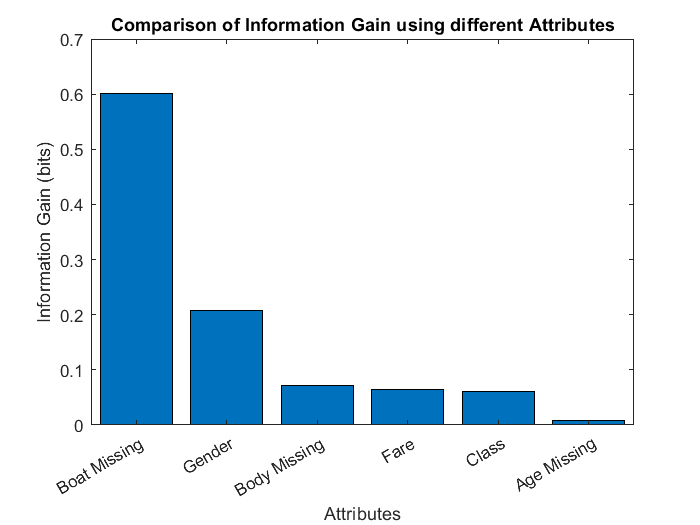

% Write your code here

% Loop through 1 to 200
for PL=1:200
    
    % Fit a tree whose maximum number of splits = PL (counter)
    t = fitctree(passengerData_newAttr_train, survivedData_train, ...
        "SplitCriterion","deviance", ...
        "CategoricalPredictors",["is_age_missing",'sex',"pclass", "embarked","sibsp","parch"], ...
        "MaxNumSplits",PL);
    
    % Use the fitted decision tree to predict survival values of the validation set
    predictedValn = t.predict(passengerData_newAttr_val);

    
    % Compute accuracy (correctness of predictions compared to validation set)
    accuracyVal = nnz(predictedValn == table2array(survivedData_val))/numel(survivedData_val);
    
    plot(PL,accuracyVal,'gd');  % Produce a plot
    hold on;                    % Prepare to superpose
    
    % Use the fitted decision tree to predict survival values of the training set
    predictedTrainn = t.predict(passengerData_newAttr_train);
    
    % Compute accuracy (correctness of predictions compared to training set)
    accuracyTrain = nnz(predictedTrainn == table2array(survivedData_train))/numel(survivedData_train);
    
    plot(PL,accuracyTrain,'rx');  % Produce a plot
    
    % ----------------------------------------Part b----------------------------------------------- %
    
    % Fit another tree with cross validation activated
    tCV = fitctree(passengerData_newAttr_train, survivedData_train, ...
        "SplitCriterion","deviance", ...
        "CategoricalPredictors",["is_age_missing",'sex',"pclass", "embarked","sibsp","parch"], ...
        "MaxNumSplits",PL, ...
        'CrossVal','on');
    
    % Compute cross validation error using kfold loss
    cvError = 1-kfoldLoss(tCV);
    
    % Produce a plot of cross validation loop vs maximum number of splits
    plot(PL,cvError,'ko');
    
    % Add legend, labels, and title
    legend('Validation Set','Training Set', 'Kfold Loss');
    ylabel('Accuracy');
    xlabel('Maximum Number of Splits');
    title('Accuracy vs. Maximum Number of Splits');
    
end
hold off;

Based on this graph, what you recommend as a sensible value for `MaxNumSplits`*?* Justify your answer.

*    - For optimal performance overfitting must be avoided, as such, adding nodes (splits) to the tree must stop when the training and validation set start to differ in performance. It can be seen from the plot that the validation and training set overlap from around 20-40 splits. Selecting a max number of splits lower than 20 would result in underfitting, and similarly, selecting a maximum number of splits above 40 would result in overfitting. The mose sensible value for the max number of splits is therefore 40, as beyond that point is the graph, the performance of the validation and training sets begin to vary greatly*

***b)*** You may notice that if you run your code with a different set of training/validation data, the graph is quite different.  A more robust approach is to perform a k-fold cross validation - i.e. produce *k* different splits, calculate the accuracy of each when predicting the training set and then plot the average across the *k* splits.  Modify your code above to use the `CrossVal` method (see documentation for `fitctree`) then plot the accuracy of the k-fold cross-validated model using the `kfoldLoss` function.

% Write your code here --- CODE SHOWN IN PREVIOUS SECTION

% Code in previous section modified as per task request


Based on this graph, what you recommend as a sensible value for `MaxNumSplits`? Justify your answer.

*    - The Kfold loss (shown as black circles in the plot) follow a trend in which accuracy decreases slowly as the maximum number of splits increases (a sign of overfitting), and as shown on the plot, the value with has the highest Kfold accuracy is around 40 aswell, matching the previous selection.*

Which of these two estimates would you recommend using for building a model? Justify your answer.

*    - Since both, values are the same, the recommended value for building the model is 40. In order to elaborate further on this, a few other things must be considered, these include the fact that if the split between the validation and training set was changed, the plots of the training and validation sets will vary greatly, however, there will be minimal changes in terms of the Kfold loss plot. So were the values different, the more reliable one to use would be that of the Kfold loss.*

***3. ***Next, we will move from using decision trees to using random forests.  To do this, we will use a MATLAB function, `fitcensemble`, that fits an ensemble of decision trees (i.e. a random forest). 

***a)*** To do this, you must first create a 'template tree', using the `templateTree `function in MATLAB.  You should pass the same name-value arguments as you did when you created a decision tree in Task 1 of this part.

% Write your code here

% Create a tree template
treeTemplate = templateTree("SplitCriterion","deviance", ...
    "CategoricalPredictors",["is_age_missing",'sex', "pclass", "embarked","sibsp","parch"]);

***b)*** Write code that trains a random forest with an increasing number of trees (from 1 to 80) using the `fitcensemble `function.  You will need to pass the training data set and classes to this function and instruct it to use bagging (see Lecture 2) by passing the `'Method', 'bag' `argument.  You should also use the `'Learner'` option to pass the template tree you created ensure you configure it to use the correct number of trees.  Then, compute the classification error on the validation set as the size of the forest is increased from 1 to 80 and plot a graph of this.

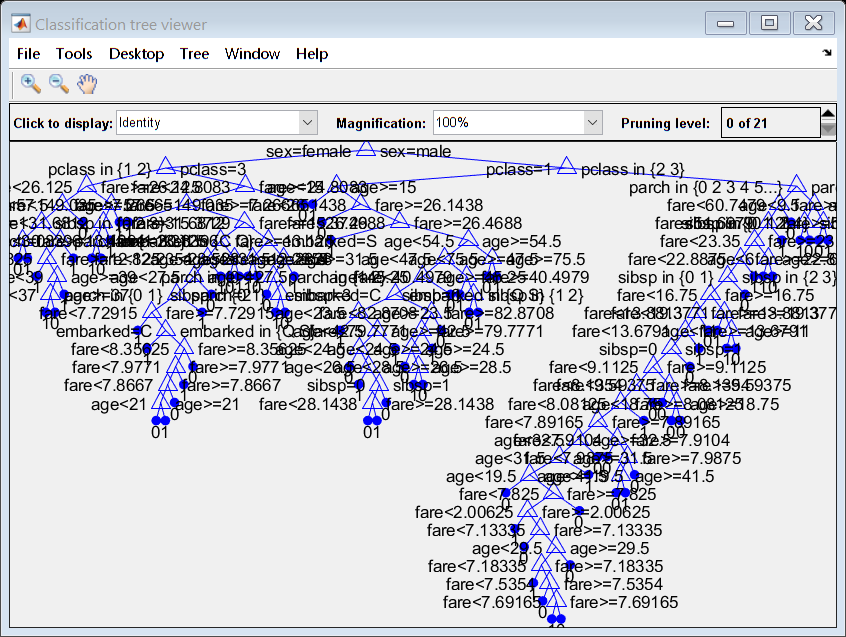

% Write your code here
for ntrees = 1:80

    
    % Recreate the tree template and add max number of splits = counter to it
    treeTemplate = templateTree("SplitCriterion","deviance", ...
        "CategoricalPredictors",["is_age_missing",'sex',"pclass", "embarked","sibsp","parch"], ...
        'MaxNumSplits', ntrees);
    
    % Create a new random dataset by sampling with replacement from original data
    % Fit ensemble of learners for classification (random forest)
    Mdl = fitcensemble(passengerData_newAttr_train,survivedData_train, ...

importance =    0.000517200199597   0.001175893455129   0.000564958091139   0.000212586239217   0.000120065326951   0.000834818742768   0.000050944480973                   0


        'Method', 'bag', ...
        'Learners', treeTemplate);
    
    % Predict values of validation set using number of trees in forest = counter
    predictedMdlVal = predict(Mdl,passengerData_newAttr_val);
    
    % Compute the accuracy of the predictions
    accuracyMdlVal = nnz(predictedMdlVal == table2array(survivedData_val))/numel(survivedData_val);
    
    % Produce a plot to compare the preformance with the number of trees in the forest
    plot(ntrees,1-accuracyMdlVal,'mo');
    

propCorrect =    0.820809248554913


    % Add labels and title
    hold on;
    xlabel('Number of Trees');
    ylabel('Error');
    title('Relation between number of trees in random forest and error');
    
end
hold off;

What do you think is the best size of forest to use? Justify your answer.  You may need to consider how you can apply techniques such as cross-validation to get a 'smoother' looking curve.

*    - The best size of forest to use would be that producing the lowest error, as such, from the plot, it can be seen that the best forest sizes are between 19-30. This range is not a definitive answer, and is therefore not very helpful, however, using cross validation techniques will produce a smoother curve which will have a definitive answer, or atleast, a narrower range. As such, by uncommenting and adding the following code into the previous loop a smoother plot can be obtained, however this slows down execution time..*

%
%     % Fit a new model of the forest with cross validation enabled
%     Mdl2 = fitcensemble(passengerData_newAttr_train,survivedData_train,
%           'Method', 'bag',
%           'Learners', treeTemplate ,
%           'CrossVal','on');
%
%     % Compute cross validation error using kfold loss
%     cvError2 = 1-kfoldLoss(Mdl2);
%
%     % Produce a plot of cross validation loop vs maximum number of splits
%     plot(ntrees,cvError2,'k+');

***c) ***Instead of testing on the validation set, which wastes data, you can do something similar to cross-validation that involves testing each tree in the forest on 'out-of-bag' data, i.e. data points that were not used in training that particular tree.  Plot the out-of-bag error vs. number of trees in the forest for values 1 to 80. You may find the following function useful:

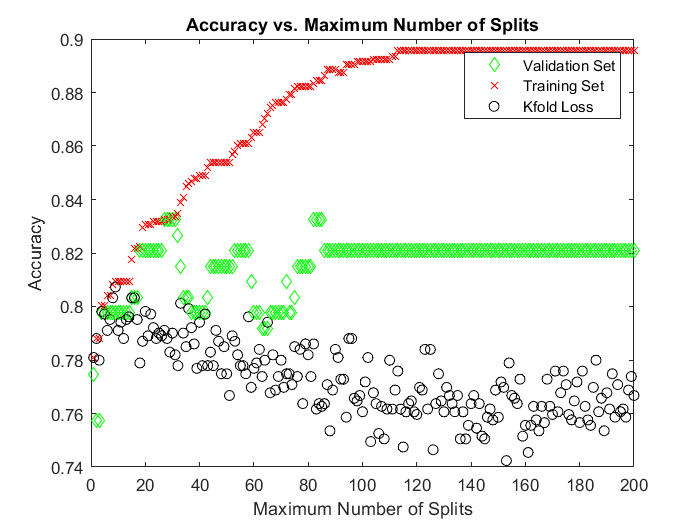

% Write your code here

for nt = 1:80

    
    % Create tree template where Maximum Number of Splits = counter
    treeTemplate = templateTree("SplitCriterion","deviance", ...
        "CategoricalPredictors",["is_age_missing",'sex',"pclass", "embarked","sibsp","parch"], ...
        'MaxNumSplits', nt);
    
    % Create a new random dataset by sampling with replacement from original data 
    % Fit ensemble of learners for classification (random forest)
    Mdl2 = fitcensemble(passengerData_newAttr_train,survivedData_train, ...
        'Method', 'bag', ...
        'Learners', treeTemplate);
    
    % Compute out-of-bag error of current model
    oobError = oobLoss(Mdl2);
    
    % Produce a plot of out-of-bag error vs number of trees in forest
    plot(nt,oobError,'mo');
    hold on;
    
    % Add labels and title
    xlabel('Number of Trees');
    ylabel('Out-of-bag Error');
    title('Out-of-bag error vs. Number of Trees in Forest');
    
end
hold off;

Based on the out-of-bag error, what do you think is the best size of tree to use? Justify your answer.

*    - Compared to the previous plot, this plot follows a more logical trend, which is, the higher the number of trees in the forest, the more well trained the system is, and thus, the lower the error up to a certain point where it flattens out (due to reaching highest achievable accuracy). This is the general trend (curve) the plot follows, however, as seen, some points are scattered about, and the number of trees which produces the lowest error are 35 and 79. Of note however, is the fact that upon rerunning this code, different minima values are produced, this is simply because the process of generating a random forest is unsurprisingly a random process. Therefore, a more suitable way of answering this question is using a range, rather than a fixed value. This being said, upon rerunning the code several times, an observation was made, it was that the values that are most likely to produce the least error (most frequent minima value) is between 33-45 inclusive.*

***d)*** Using this out-of-bag error approach can give an indication of variable importance.  This can be done using the out-of-bag permutation approach. This effectively random permutes a variable (e.g. `pclass`) and then records how much worse the classification error becomes.  If error does not change much then this variable must not have much influence on predicting class.  Compute out-of-bag error importance estimates from your forest using the `oobPermutedPredictorImportance` function.

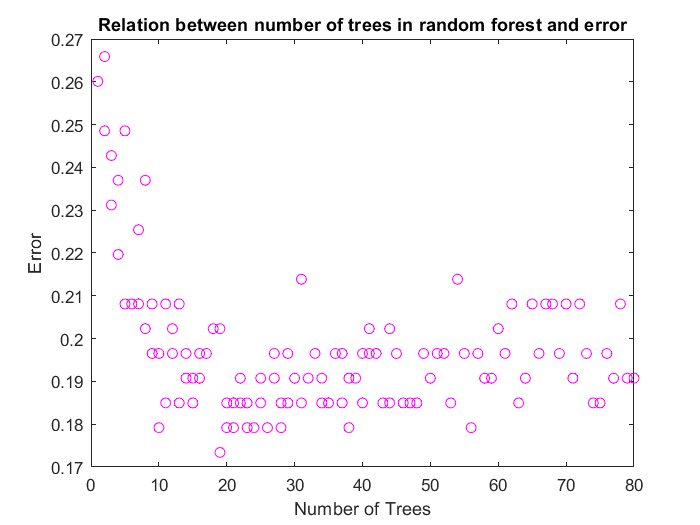

% Write your code here

% Compute the out-of-bag importance of predictors
imp = oobPermutedPredictorImportance(Mdl);


% Plot a bar chart
figure;
bar(imp);

% Add title and labels
title('Out-of-Bag Permuted Predictor Importance Estimates');
ylabel('Estimates');
xlabel('Predictors');

% Adjust tables
h = gca;
h.XTickLabel = Mdl.PredictorNames;
h.XTickLabelRotation = 45;
h.TickLabelInterpreter = 'none';

What are the three most important variables? Does this agree with your findings from the classification tree and entropy analysis? If not, which do you think is most reliable.  Justify your answer.

*    - The three most important variables are sex, pclass, and fare, respectively. This results agree with all previous findings and further validates them.*

***4. ***Using the methods you have developed so far, write code that trains a Random Forest classifier on the full data set in the file `passengers.csv` and then takes in a second file, `passengersVal.csv`, that does not contain any survival variable, and performs predictions of survival on these data points. A sample `passengersVal.csv `file (containing data already in the training set) has been provided. For marking a different data file, containing passenger data not in the original `passengers.csv` file, will be used to test how well your Random Forest classifer predicts survival. For training and prediction use only the following attributes: `{'pclass', 'sex', 'age', 'sibsp', 'parch', 'fare', 'embarked'}`. To be clear, your final code must read in and perform prediction on the `passengersVal.csv` file.

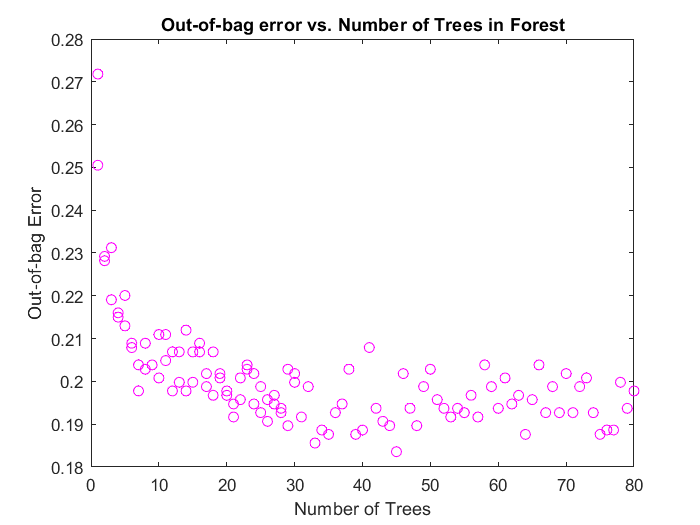

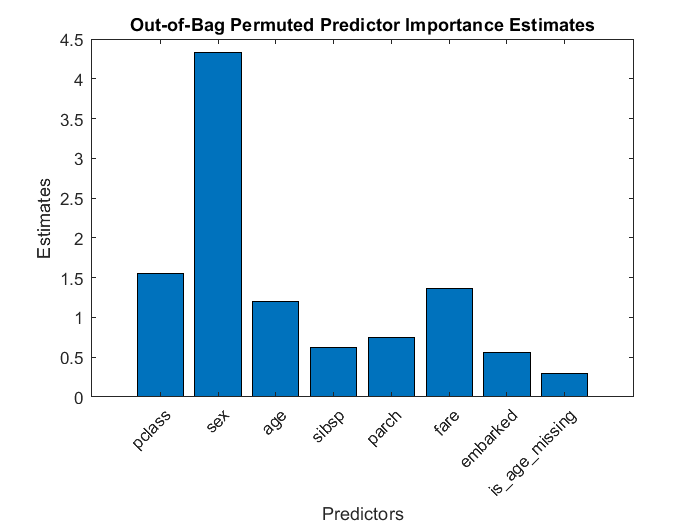

accuracyVals =    0.875238095238095


% Write your code here

% Declare Validation set

ValidationData = readtable('passengersVal.csv');
TrainingData = removevars(passengerData, ...
    {'survived','name','ticket','cabin','boat','body','home_dest'});
SurvivedValidationData = ValidationData.survived;
ValidationData = removevars(ValidationData, ...
    {'survived','name','ticket','cabin','boat','body','home_dest'});

% Creat Tree Template
treeTemplate = templateTree("SplitCriterion","deviance", ...
    "CategoricalPredictors",['pclass', 'sex', 'sibsp', 'parch', 'embarked'], ...
    'MaxNumSplits',[14]);

% Create a new random dataset by sampling with replacement from original data 
% Fit ensemble of learners for classification (random forest)
Mdl2 = fitcensemble(TrainingData,passengerData.survived, ...
    'Method', 'bag', ...
    'Learners', treeTemplate);

% Predict values of validation set using number of trees in forest with lowest error
predictedVals = predict(Mdl2,ValidationData);

% Compute the accuracy of the predictions
accuracyVals = 1 - nnz(predictedVals == SurvivedValidationData)/numel(ValidationData);

% Display
accuracyVals